syms x y
z_total = 0;

%positions = [0.75 -2.5; -0.25 1];
%a = 1;
% z_total = makeDivot(positions(2,:),z_total,a);
% z_total = makeDivot(positions(1,:),z_total,a);

a_divot = -5;
a_barrel = 5;

% top right obstacle
% bottom to left
startPoint = [-0.25+0.25*sqrt(2) -1]; % bottom
endPoint = [-0.25 -1-0.25*sqrt(2)]; % left
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);
% left to top
startPoint = [-0.25 -1-0.25*sqrt(2)]; % left
endPoint = [-0.25-0.25*sqrt(2) -1]; % top
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);
% top to right
startPoint = [-0.25 -1+0.25*sqrt(2)]; % right
endPoint = [-0.25-0.25*sqrt(2) -1]; % top
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);
% right to bottom
startPoint = [-0.25 -1+0.25*sqrt(2)]; % right
endPoint = [-0.25+0.25*sqrt(2) -1]; % bottom
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);


% bottom right obstacle
% bottom to left
startPoint = [1+0.25*sqrt(2) -0.7]; % bottom
endPoint = [1 -0.7-0.25*sqrt(2)]; % left
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);
% left to top
startPoint = [1 -0.7-0.25*sqrt(2)]; % left
endPoint = [1-0.25*sqrt(2) -0.7]; % top
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);
% top to right
startPoint = [1 -0.7+0.25*sqrt(2)]; % right
endPoint = [1-0.25*sqrt(2) -0.7]; % top
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);
% right to bottom
startPoint = [1 -0.7+0.25*sqrt(2)]; % right
endPoint = [1+0.25*sqrt(2) -0.7]; % bottom
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);



% bottom left obstacle
% bottom left to top left
startPoint = [1.41+0.25 -2-0.25]; % bottom
endPoint = [1.41-0.25 -2-0.25]; % top
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);
% top left to top right
startPoint = [1.41-0.25 -2-0.25]; % left
endPoint = [1.41-0.25 -2+0.25]; % right
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);
% top right to bottom right
startPoint = [1.41-0.25 -2+0.25]; % top
endPoint = [1.41-0.25 -2+0.25]; % bottom
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);
% bottom right to bottom left
startPoint = [1.41-0.25 -2+0.25]; % right
endPoint = [1.41+0.25 -2-0.25]; % left
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);

% barrel of benevolence
z_total = makeDivot([0.75 -2.5], z_total, a_barrel);


% top wall
% bottom left to top left
startPoint = [-1.5 -3.37]; % left
endPoint = [-1.5 1]; % right
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);


%right wall
% top right to bottom right
startPoint = [-1.5 1]; % top
endPoint = [2.5 1]; % bottom
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);


%bottom wall
% bottom right to bottom left
startPoint = [2.5 1]; % right
endPoint = [2.5 -3.37]; % left
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);


%left wall
% bottom left to top left
startPoint = [2.5 -3.37]; % bottom
endPoint = [-1.5 -3.37]; % top
z_total = makeLineOfDivots(startPoint,endPoint,20,z_total,a_divot);

clf
[X,Y] = meshgrid(linspace(-1.5,2.5,50),linspace(-3.37,1,50));
Z = double(subs(z_total,{x,y},{X,Y}));
surf(X,Y,Z)
xlabel('i')
ylabel('j')
zlabel('k')

% % gradient ascent
% barrel_pos = [0.75 -2.5 a_barrel];
% curr_pos = [0 0 0];
% while curr_pos ~= barrel_pos
%     orientation_vec = gradient(z_total,curr_pos);
%     curr_pos(1) = curr_pos(1) + orientation_vec(1);
%     curr_pos(2) = curr_pos(2) + orientation_vec(2);
%     curr_pos(3) = curr_pos(3) + orientation_vec(3);
% %     placeNeato(curr_pos);
% end 

flatland_assignment(-z_total)

r_g = makeMap();
[fitline_coefs,bestInlierSet,bestOutlierSet,bestEndPoints] = robustLineFit(r_g, 0.1, 16);

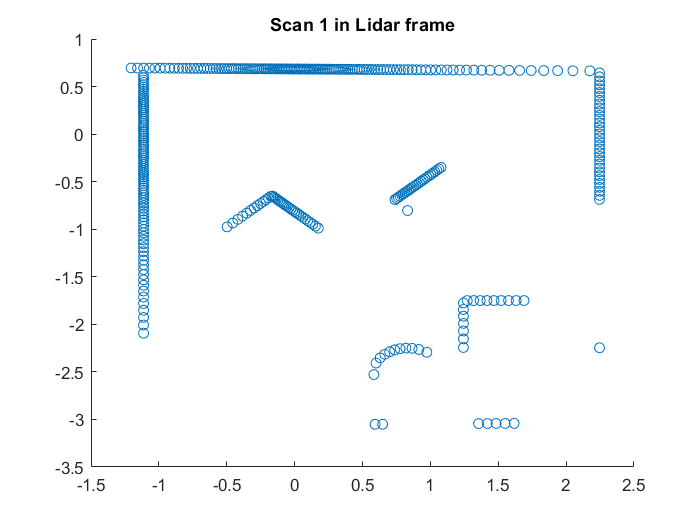

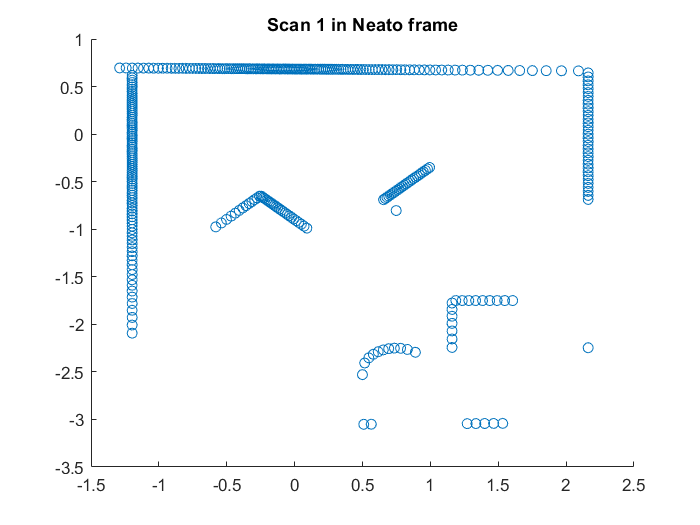

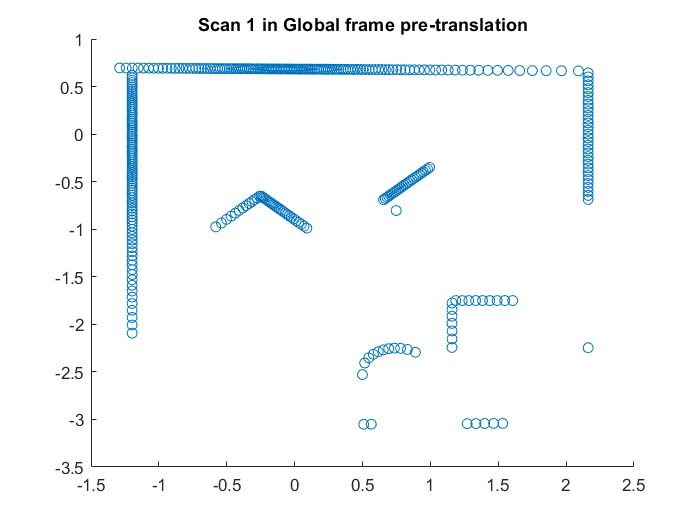

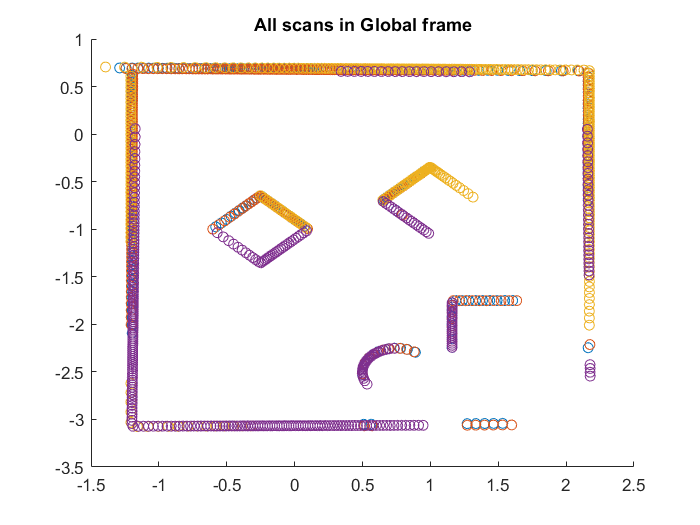

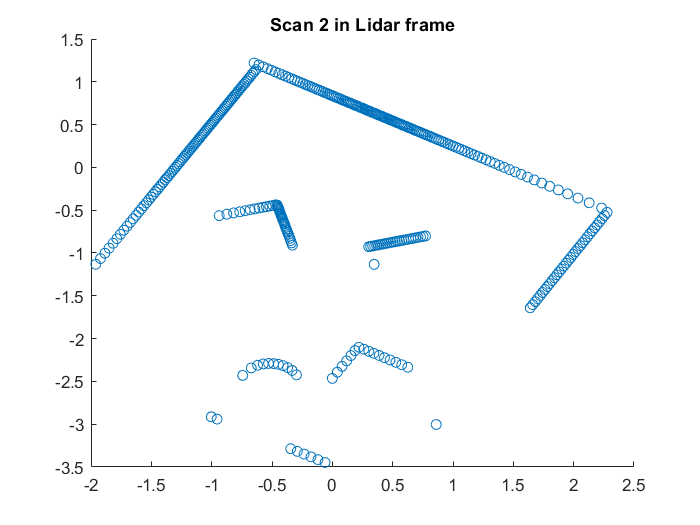

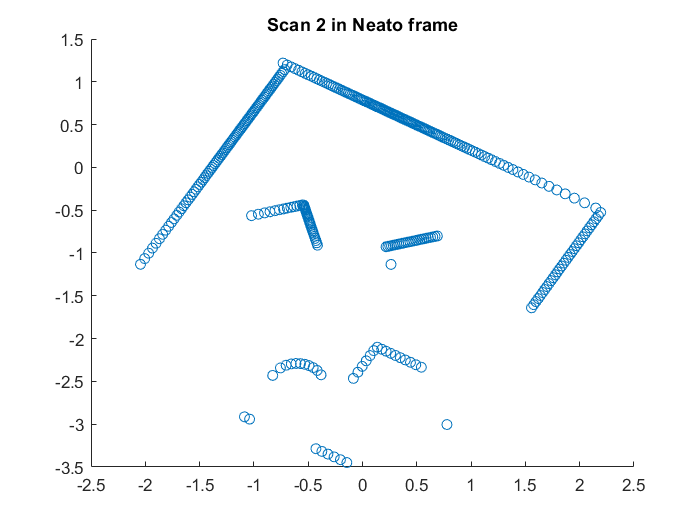

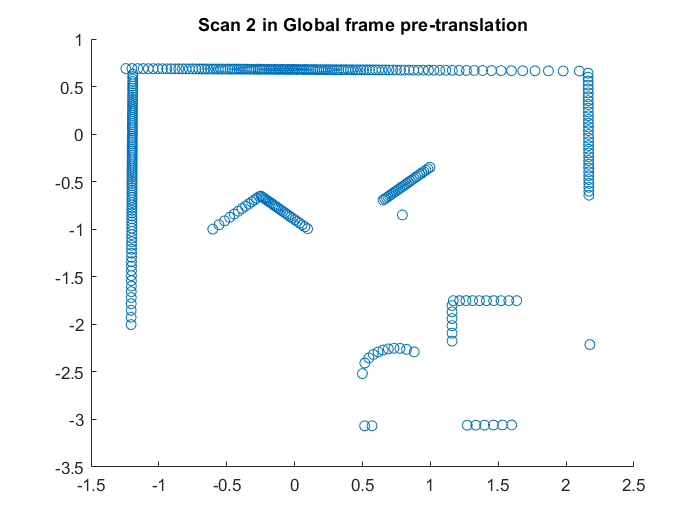

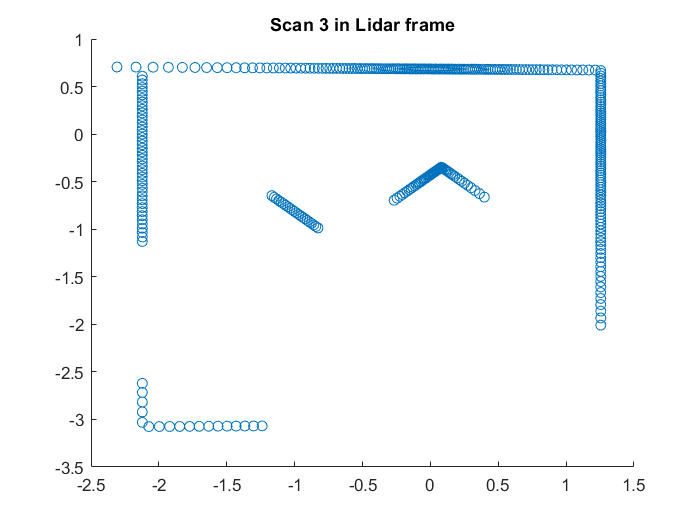

% close all

%Script to identify multiple lines in a scan
r_g = makeMap();

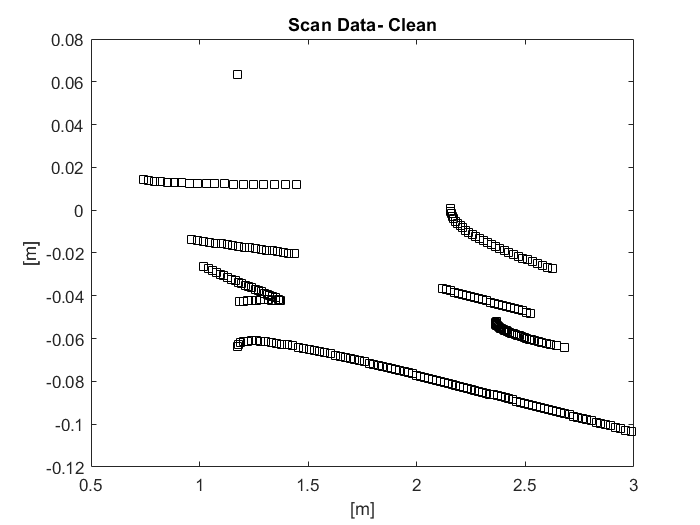

[theta, r] = cart2pol(r_g(1, :), r_g(2, :));

%eliminate zeros and sample farther than 3m (range of LIDAR)
index=find(r~=0 & r<3);
r_clean=r(index);
theta_clean=theta(index);

%plot the polar data as verification
% figure(1)
% polarplot(deg2rad(theta_clean),r_clean,'ks','MarkerSize',6,'MarkerFaceColor','m')
% title('Visualization of Polar Data')

%convert to Cartesian and plot again for verification
[x,y]=pol2cart(deg2rad(theta_clean),r_clean);
points=[x,y];
figure(2)
plot(x,y,'ks')
title('Scan Data- Clean')
xlabel('[m]')
ylabel('[m]')

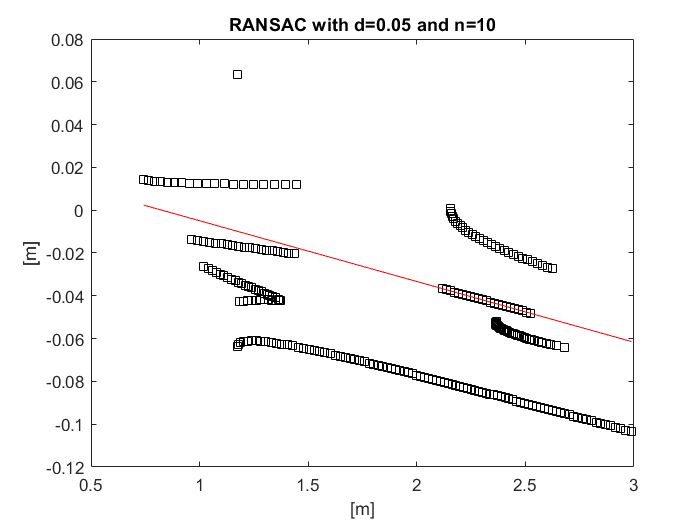


bestOutlierSet=points;
nn=1;
visualize=0;
d=0.05;
n=10;
while size(bestOutlierSet,1) > 5
    [fitline_coefs(nn,:),bestInlierSet,bestOutlierSet,bestEndPoints(:,:,nn)]= robustLineFit(r_clean,theta_clean,d,n,visualize);
    
    if isnan(fitline_coefs(nn,1))
        disp('All Lines Identified')
        break;
    end
    
    [theta_clean,r_clean]=cart2pol(bestOutlierSet(:,1),bestOutlierSet(:,2));
    theta_clean=rad2deg(theta_clean);
    
    nn=nn+1;
end

figure;
plot(x,y,'ks')
hold on
for kk=1:size(bestEndPoints,3)
    plot(bestEndPoints(:,1,kk), bestEndPoints(:,2,kk), 'r')
end
title(['RANSAC with d=' num2str(d) ' and n=' num2str(n)])
xlabel('[m]')
ylabel('[m]')